# IIR FIlters

- infinite impulse response filter

- use 2 sets of coefficients, one for values of original signal, one for values of filtered signal

## Butterworth filter

sample_rate = 1024;
nyquist = sample_rate/2;
freq_range = [20 45];

% 4th order filter 
[kernel_b,kernel_a] = butter(4, freq_range/nyquist);
% power spectrum
kernel_power = abs(fft(kernel_b)).^2;
% hz is always from - to nyquist in len(kernel)/2 bins
hz_vals = linspace(0, nyquist, floor(length(kernel_b)/2)+1);

- Plot the kernel

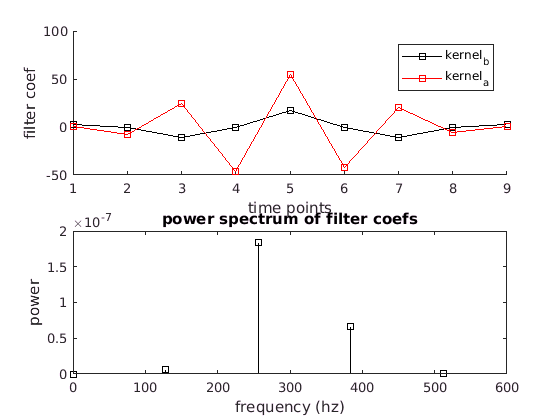

f1 = figure(1); clf;
%f1.Position = [0 0 800 500];
subplot(211);
hold on;
plot(kernel_b*1e5, 'ks-');
plot(kernel_a, 'rs-');
xlabel("time points");
ylabel("filter coef");
legend(["kernel_b", "kernel_a"]);
hold off;

subplot(212);
stem(hz_vals, kernel_power(1:length(hz_vals)), 'ks-');
xlabel("frequency (hz)");
ylabel("power");
title("power spectrum of filter coefs");

## Use an impulse response to evaluate a filter

impulse = [zeros(1,500) 1 zeros(1,500)];

- plot the impulse

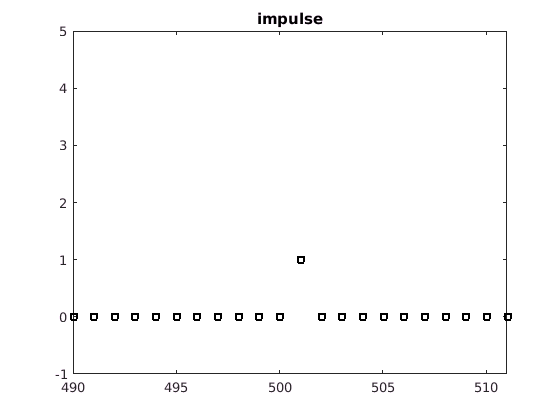

f2 = figure(2); clf;
plot(impulse, 'ks', 'linew', 2);
title("impulse");
xlim([490 511]);
ylim([-1 5]);

- apply the filter

response = filter(kernel_b, kernel_a, impulse);

- compute power spectrum

res_powers = abs(fft(response)).^2;
hz_vals = linspace(0, nyquist, floor(length(res_powers)/2) + 1);

- plot the response

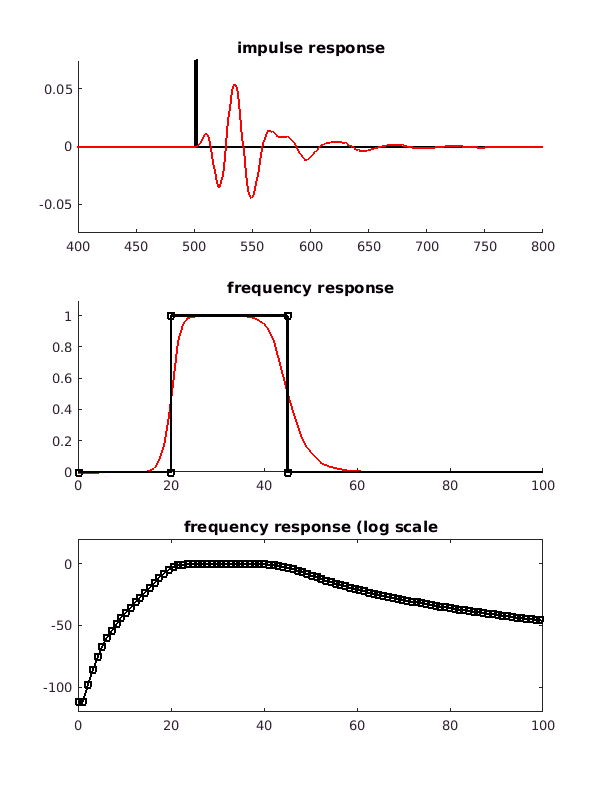

f3 = figure(3); clf;
f3.Position = [0 0 600 800];
subplot(311);
hold on;
plot(impulse, 'k', 'linew', 2);
plot(response, 'r', 'linew', 2);
xlim([400 800]);
ylim([-.075 .075]);
title("impulse response");
hold off;

subplot(312);
hold on;
plot(hz_vals, res_powers(1:length(hz_vals)), 'r', 'linew', 2);
plot([0 freq_range(1) freq_range freq_range(2) nyquist], [0 0 1 1 0 0], 'ks-', 'linew', 2);
xlim([0 100]);
ylim([0 1.1]);
title("frequency response");
hold off;

subplot(313);
plot(hz_vals, 10*log10(res_powers(1:length(hz_vals))), 'ks-', 'linew', 2);
xlim([0 100]);
ylim([-120 20]);
title("frequency response (log scale");